%Import "detector" variable (previously trained object detector)
load detectorACF.mat;

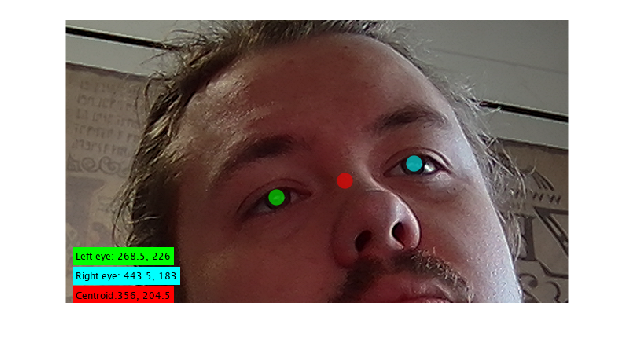

Error using webcam>@(obj,value)obj.setDynamicProperty(prop.Name,value)
The property Zoom must be specified as a numeric scalar between 100 and 400.

%Camera setup
cam = webcam;
cam.Resolution = "640x360";
cam.Zoom = 400;
%Instantiate gpuImage in GPU memory
gpuImage = gpuArray(uint8(zeros(360,640,3)));

for i = 1:100
    %take snapshot
    gpuImage = cam.snapshot;
    %flip to achieve mirrored image
    gpuImage = flip(gpuImage, 2);
    
    [x1, y1, x2, y2] = getEyes(gpuImage,detectorACF);

    if isempty(x1) || isempty(y1) || isempty(x2) || isempty(y2)
        break;

    else
        %store coordinates of halway point between eyes
        centroid = [((x1+x2)/2) ((y1+y2)/2)];

        gpuImage = insertShape(gpuImage,"filled-circle",[x1 y1 10],"LineWidth",5,"Color","green");
        gpuImage = insertShape(gpuImage,"filled-circle",[x2 y2 10],"LineWidth",5,"Color","cyan");
        gpuImage = insertShape(gpuImage,"filled-circle",[centroid 10],"LineWidth",5,"Color","red");
        gpuImage = insertText(gpuImage,[10 290],"Left eye: " + x1 + ", " + y1,"BoxColor","green","BoxOpacity",1);
        gpuImage = insertText(gpuImage,[10 315],"Right eye: " + x2 + ", " + y2,"BoxColor","cyan","BoxOpacity",1);
        gpuImage = insertText(gpuImage,[10 340],"Centroid:" + centroid(1) + ", " + centroid(2), ...
            "BoxColor","red","BoxOpacity",1);
    end

    imshow(gpuImage);
end

clear cam;